# CAPÍTULO 09 - RESISTENCIA EN ESTADOS TENSIONALES COMPLEJOS

Comprueba una estructura espacial de sección circular maciza o tubular, localiza barras y secciones críticas y, si lo deseas, dimensiona un diámetro uniforme. También puedes introducir directamente los esfuerzos de una sección.

Dimensión: estructura 3D o sección aislada. La geometría, la deformada, los seis esfuerzos y la comprobación de resistencia se calculan a partir de los datos.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

modo="estructura" o "seccion". evaluacion="comprobar" o "dimensionar" se usa con estructura. En estructura, nodos, cargas, apoyos y qGlobal siguen exactamente el formato espacial del capítulo 7. El ejemplo inicial es una ménsula acodada cargada fuera de su plano. Sustituye estas tablas para representar otra geometría.

modo="estructura"; evaluacion="comprobar";
nodos=[0 0 0;.6 0 0;.6 0 .3]; barras=[1 2;2 3];
E=210e9; nu=.3; G=E/(2*(1+nu));
cargas=[3 0 -450 -150 0 0 0]; apoyos=[1 0 0 0 0 0 0];
qGlobal=zeros(size(barras,1),6); qLocal=zeros(size(barras,1),8);
referenciaY=zeros(size(barras,1),3);liberaciones=zeros(0,3);
D=.03; di=0; espesor=[];
limiteTraccion=160e6;limiteCompresion=160e6;
teoria=4; nRequerido=1; considerarCortante=true;
intervaloDiametro=[.015 .12]; puntosLongitud=121; puntosAngulares=360;
vistaEpiuras="ambas"; mostrarCeros=false;
N=20000;Qy=0;Qz=0;My=800;Mz=1200;T=600;

D y di son diámetros exterior/interior en m, escalares o un valor por barra. espesor=[] conserva di; si escribes un espesor positivo, di=D-2·espesor. teoría: 1=normal máxima, 2=deformación máxima, 3=Tresca, 4=von Mises, 5=Mohr. Las teorías 1–4 usan límites simétricos; Mohr utiliza la razón de límites de tracción/compresión. El dimensionamiento admite un único D uniforme; conserva el diámetro interior o el espesor indicado y vuelve a resolver la estructura en cada evaluación.

## 2. Esfuerzos y tensiones en los ejes locales


$$F=\frac{\pi}{4}(D^2-d_i^2),\quad I_y=I_z=\frac{\pi}{64}(D^4-d_i^4),\quad J=2I$$



$$\sigma_x=\frac{N}{F}+\frac{M_yz-M_zy}{I},\qquad \tau_{xy,T}=-\frac{Tz}{J},\quad \tau_{xz,T}=\frac{Ty}{J}$$


En estructura, My y Mz son momentos vectoriales de mano derecha, como las flechas locales del capítulo 7. En modo seccion, el dato My conserva la convención escalar anterior: se convierte mediante My_vectorial=-My. Así se mantiene el significado de los datos de sección que ya utilizabas. Las reacciones siguen siendo globales.

## 3. Comprobación del cortante transversal


$$Q=\sqrt{Q_y^2+Q_z^2},\quad \tau_{Q,\max}\simeq\frac{Q\,S_0}{I b_0},\quad S_0=\frac23(R^3-r_i^3),\quad b_0=2(R-r_i)$$



$$|\tau|\leq |\tau_{T,\max}|+\tau_{Q,\max},\qquad \sigma_{III}=\sqrt{\sigma_x^2+4\tau^2},\quad \sigma_{IV}=\sqrt{\sigma_x^2+3\tau^2}$$


considerarCortante=true combina las mayores magnitudes de cortante en una envolvente conservadora. Sus máximos no tienen por qué coincidir en el mismo punto, por eso se diferencia del mapa nominal de N, My, Mz y T. Si lo desactivas, la comprobación solo se acepta cuando la cota de cortante Q es como máximo el 5% del límite resistente; de lo contrario no se declara cumplimiento. El muestreo longitudinal debe refinarse para comprobar convergencia.

config=struct('D',D,'di',di,'espesor',espesor,'nu',nu,'limiteTraccion',limiteTraccion, ...
    'limiteCompresion',limiteCompresion,'teoria',teoria,'nRequerido',nRequerido, ...
    'puntosLongitud',puntosLongitud,'considerarCortante',considerarCortante);
if modo=="estructura"
    datos=struct('nodos',nodos,'barras',barras,'E',E,'G',G,'cargas',cargas,'apoyos',apoyos, ...
        'qGlobal',qGlobal,'qLocal',qLocal,'referenciaY',referenciaY,'liberaciones',liberaciones);
    if evaluacion=="dimensionar"
        resultado=rm_dimensionar_marco3d(datos,config,intervaloDiametro);
    else
        assert(evaluacion=="comprobar",'Evaluacion no reconocida.');
        resultado=rm_resistencia_marco3d(datos,config);
    end
    disp(resultado.tabla);
    disp(table(resultado.factor,resultado.cumple,resultado.cortanteValidado, ...
        'VariableNames',{'Factor_global','Cumple','Cortante_validado'}));
    disp('Reacciones [FX FY FZ MX MY MZ]:');disp(resultado.marco.R);
    i=resultado.barraCritica;sCritica=resultado.sCritica;a=resultado.marco.campos{i};
    N=polyval(a.N,sCritica);Qy=polyval(a.Vy,sCritica);Qz=polyval(a.Vz,sCritica);
    T=polyval(a.T,sCritica);MyVector=polyval(a.My,sCritica);Mz=polyval(a.Mz,sCritica);
    Dcrit=resultado.D(i);dicrit=resultado.di(i);
else
    assert(modo=="seccion" && isscalar(D)&&isscalar(di),'En seccion usa diametros escalares.');
    Dcrit=D;dicrit=di;if ~isempty(espesor),dicrit=D-2*espesor;end
    MyVector=-My;sCritica=0;
    resultado=rm_circular_combinada(N,Qy,Qz,T,MyVector,Mz,Dcrit,dicrit,nu,limiteTraccion/limiteCompresion);
    valores=resultado.envolvente;
    if ~considerarCortante
        assert(resultado.tauQ<=.05*limiteTraccion,'El cortante supera el umbral del 5%%. Activa considerarCortante.');
        valores=resultado.nominal;
    end
    disp(table((1:5)',valores'/1e6,limiteTraccion./max(valores',realmin), ...
        'VariableNames',{'Teoria','Equivalente_MPa','Factor'}));
end

    Barra    D_m     di_m    Equivalente_cota_MPa    Factor_seguridad    s_critica_m    tauQ_cota_MPa    tauQ_porcentaje_limite
    _____    ____    ____    ____________________    ________________    ___________    _____________    ______________________

      1      0.03     0             116.67                1.3714              0            0.89474              0.55921        
      2      0.03     0             51.163                3.1273              0            0.84883              0.53052        



    Factor_global    Cumple    Cortante_validado
    _____________    ______    _________________

       1.3714        true            true       



Reacciones [FX FY FZ MX MY MZ]:
    0.0000  450.0000  150.0000 -135.0000  -90.0000  270.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0
    0.0000   -0.0000         0   -0.0000   -0.0000         0



## 4. Geometría, sección crítica y epiuras

La geometría y las epiuras espaciales permiten comprobar por dónde pasa cada esfuerzo. La curva de tensión equivalente frente a s revisa toda la longitud, sin asumir que el empotramiento sea siempre el punto crítico. El mapa de sección representa N, flexión y torsión; la envolvente de cortante transversal se presenta por separado en las tablas.

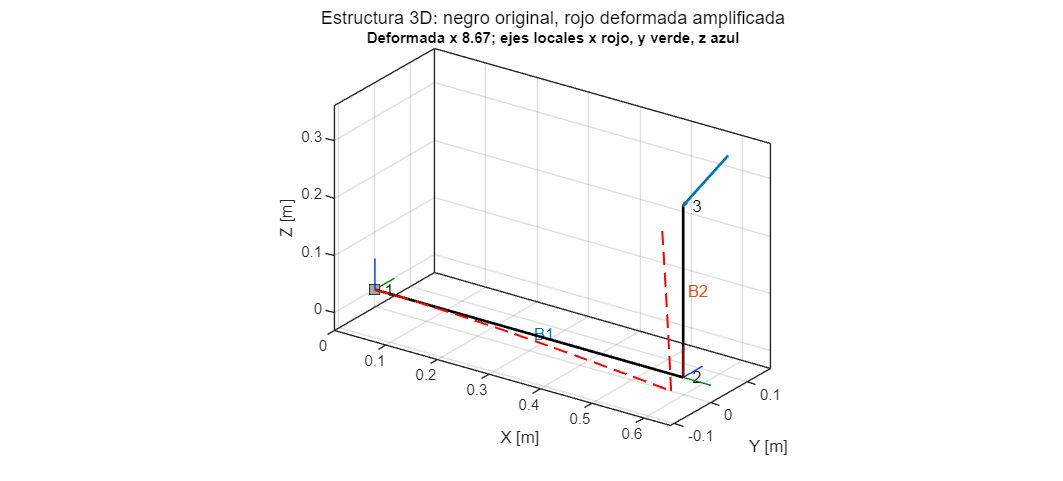

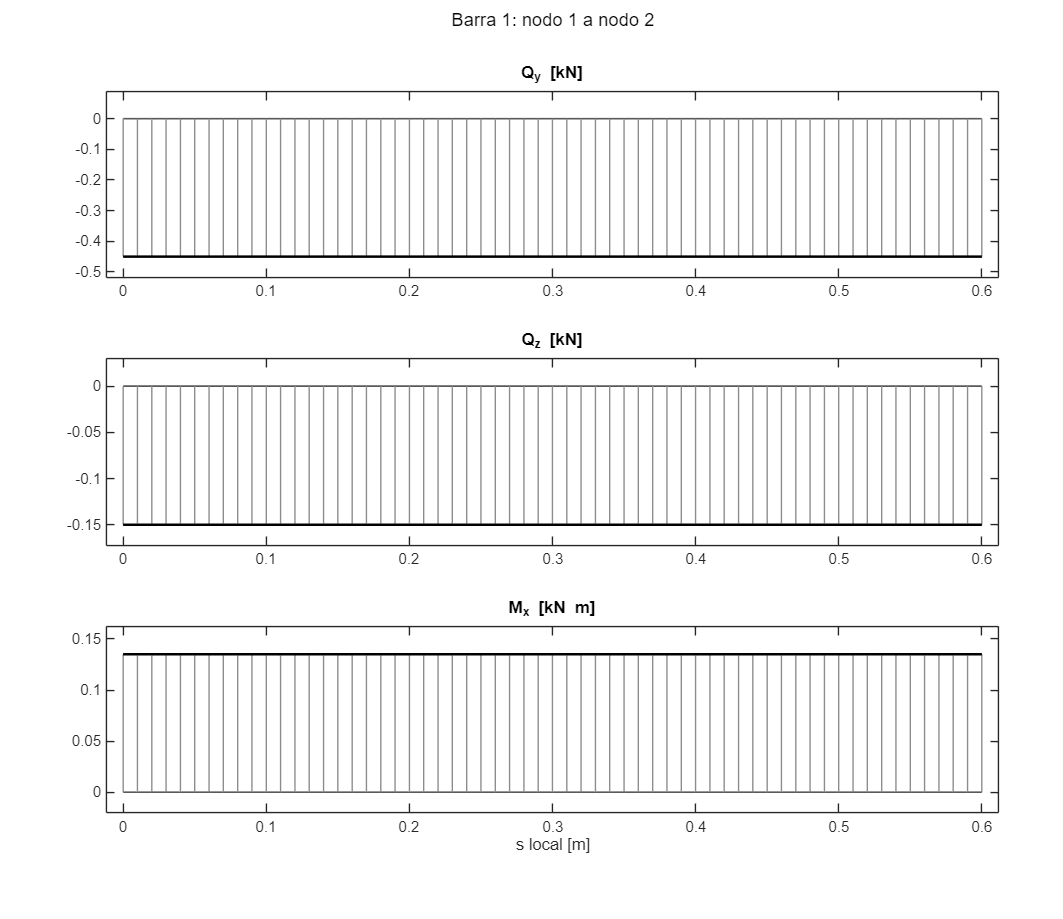

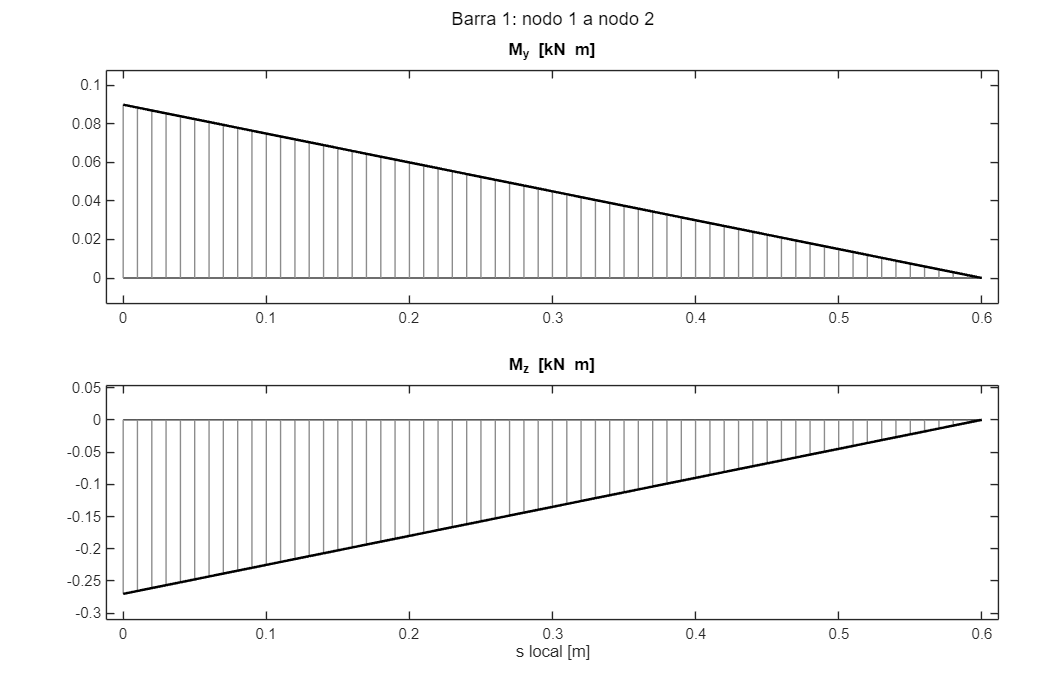

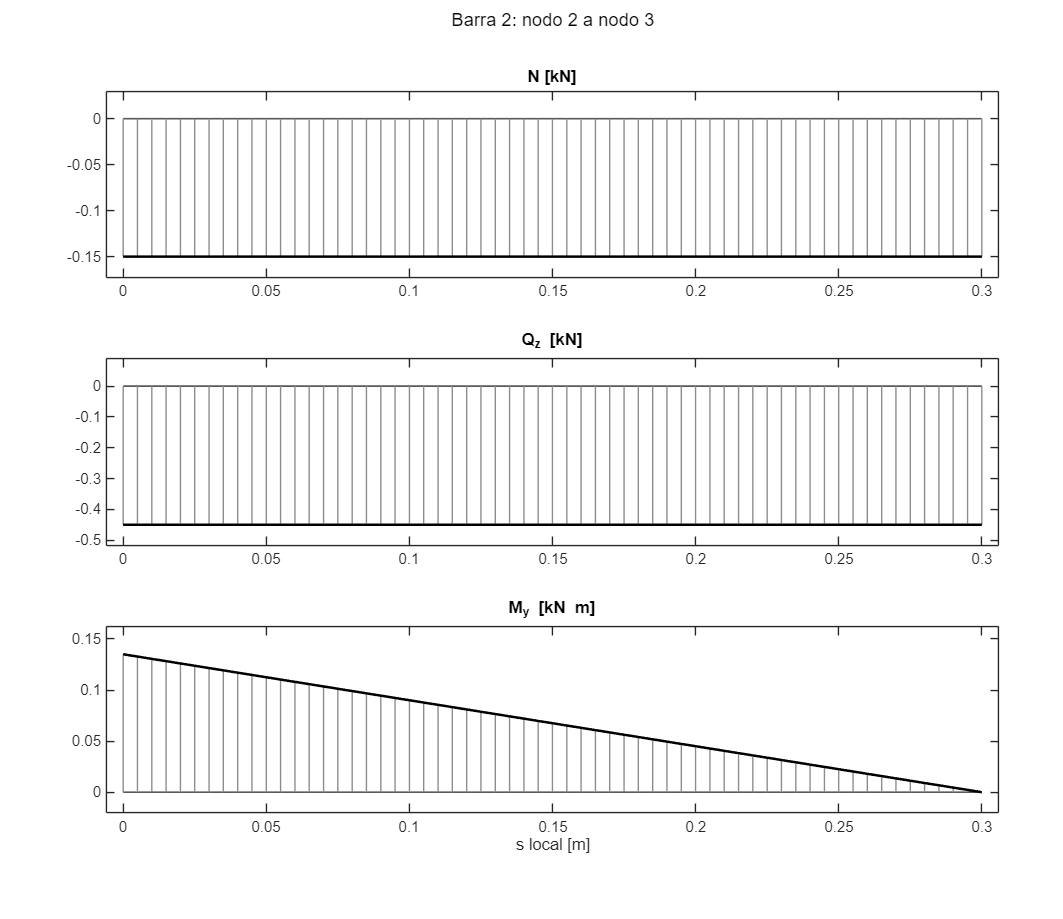

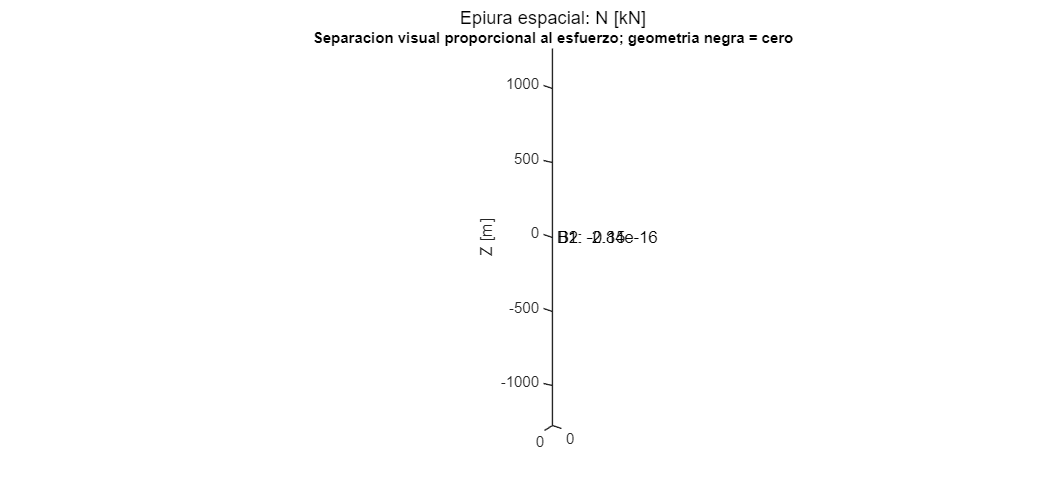

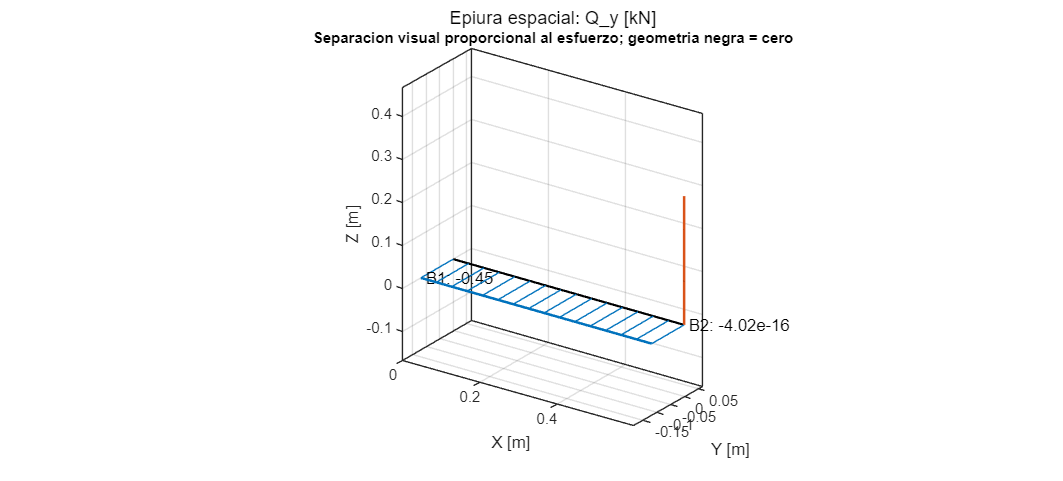

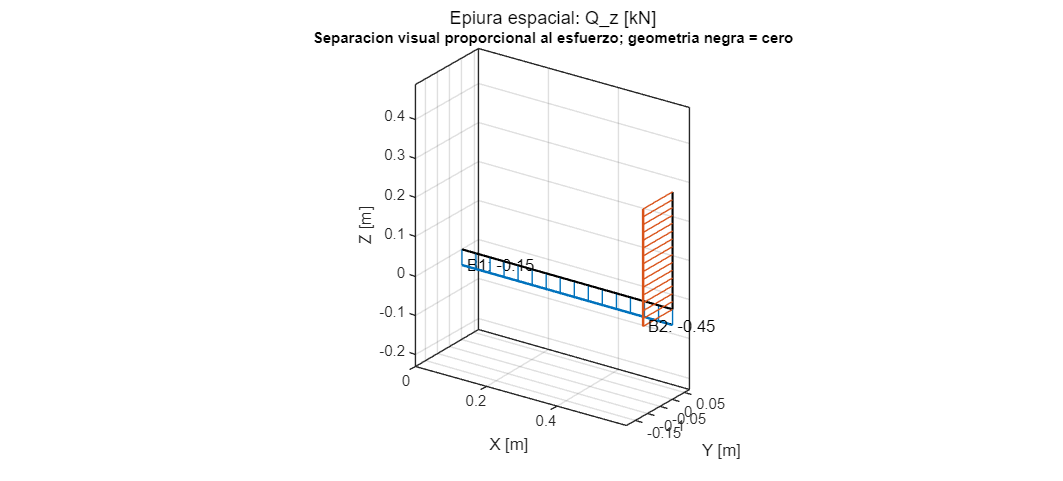

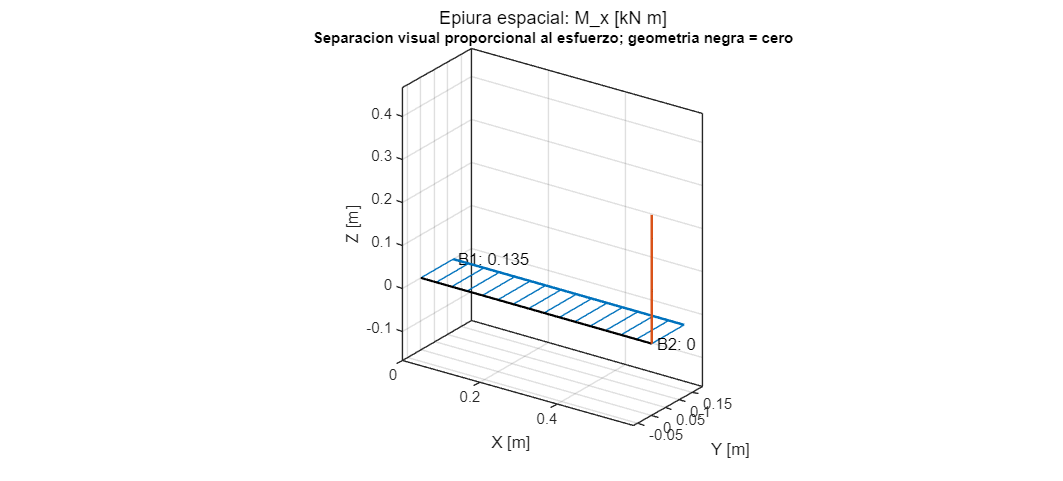

if modo=="estructura"
    figuras=rm_graficar_marco3d(resultado.marco,vistaEpiuras,mostrarCeros);
    [figura,ejes]=rm_figura(1,'Tension equivalente por barra: envolvente de comprobacion');hold(ejes(1),'on');
    for j=1:numel(resultado.campos)
        b=resultado.campos{j};plot(ejes(1),b.s,b.equivalentes(:,teoria)/1e6,'DisplayName',sprintf('Barra %d',j),'LineWidth',1.5);
    end
    yline(ejes(1),limiteTraccion/nRequerido/1e6,'r--','HandleVisibility','off');
    legend(ejes(1),'show','Location','best');xlabel(ejes(1),'s local [m]');ylabel(ejes(1),'Equivalente [MPa]');
end

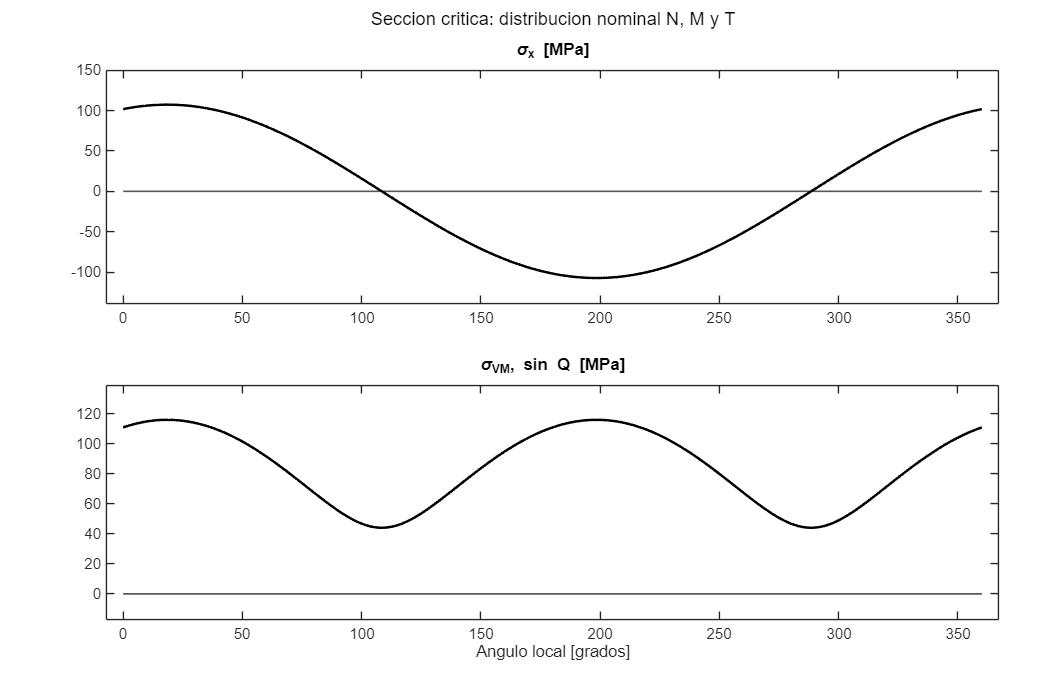

Fcrit=pi*(Dcrit^2-dicrit^2)/4;Icrit=pi*(Dcrit^4-dicrit^4)/64;Jcrit=2*Icrit;
ang=linspace(0,2*pi,puntosAngulares+1)';y=Dcrit*cos(ang)/2;z=Dcrit*sin(ang)/2;
sigma=N/Fcrit+(MyVector*z-Mz*y)/Icrit;tauT=abs(T)*Dcrit/(2*Jcrit);
eqNominal=sqrt(sigma.^2+3*tauT^2);
[figura,ejes]=rm_figura(2,'Seccion critica: distribucion nominal N, M y T');
rm_curva(ejes(1),ang*180/pi,sigma/1e6,'\sigma_x [MPa]',false);
rm_curva(ejes(2),ang*180/pi,eqNominal/1e6,'\sigma_{VM}, sin Q [MPa]',false);xlabel(ejes(2),'Angulo local [grados]');

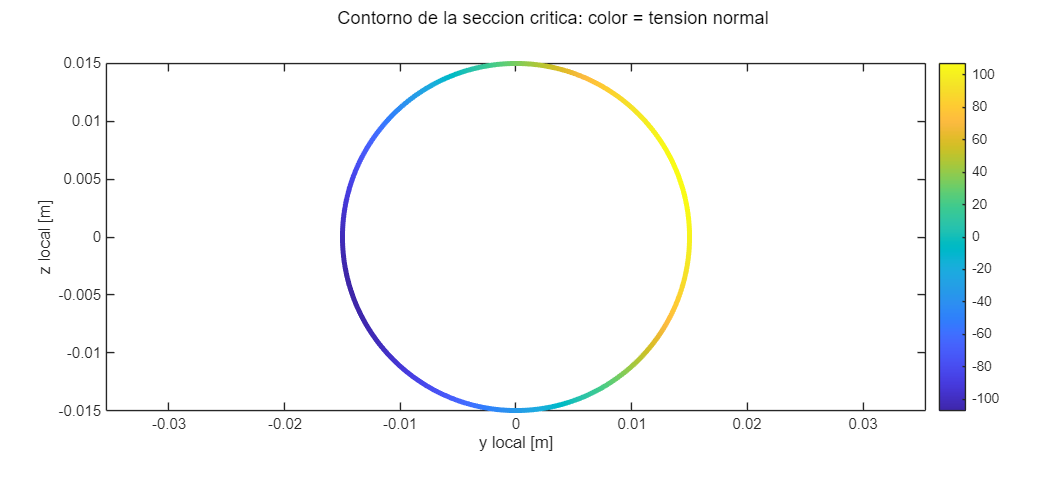

[figura,ejes]=rm_figura(1,'Contorno de la seccion critica: color = tension normal');
surface(ejes(1),[y';y'],[z';z'],zeros(2,numel(y)),[sigma';sigma']/1e6, ...
    'FaceColor','none','EdgeColor','interp','LineWidth',3);
view(ejes(1),2);axis(ejes(1),'equal');colorbar(ejes(1));xlabel(ejes(1),'y local [m]');ylabel(ejes(1),'z local [m]');

## Funciones utilizadas

rm_resistencia_marco3d: resuelve geometría y comprueba secciones. Aquí busca la barra y la posición más exigida por el criterio seleccionado.

rm_dimensionar_marco3d: busca un diámetro mediante equilibrio y resistencia. Aquí recalcula esfuerzos y rigideces en cada diámetro del intervalo.

fzero: encuentra una raíz escalar. Aquí hace coincidir el factor de seguridad con el requerido en el dimensionamiento.

hypot: calcula una magnitud de dos componentes. Aquí combina flexiones My/Mz y cortantes Qy/Qz.

surface: dibuja una superficie con color variable. Aquí colorea el contorno circular con la tensión nominal de la sección crítica.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Marcos espaciales elásticos de barras rectas circulares, con flexión en dos planos, torsión y esfuerzo axial. El cortante transversal se controla mediante una envolvente conservadora de Jourawski, no mediante un campo exacto 3D de elasticidad. El dimensionamiento es uniforme y se limita al intervalo indicado. No incluye concentraciones locales en codos/uniones, alabeo restringido, pandeo ni plastificación.

Conexión con lo anterior: Llama al mismo cálculo espacial del capítulo 7 y aplica los criterios del capítulo 8. No es necesario ejecutar esos Live Scripts antes: se reutilizan sus rutinas.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 09: calculo completado.');

Capitulo 09: calculo completado.
